oldpath = path;
path(oldpath,'D:\Turboshaft\vvod.matlab\lib\optic')

number_nodes = 50;
error_position = 0;

savingMode = 1;
description = '';
mode_flame = "equable";
matoh = 0;
tic
[result, res_matrix, ligth_start_coordX] = race_tracing(number_nodes, error_position, savingMode, description, mode_flame, matoh);
toc

Определение кyрайних положений волокна

Добавление папки с библиотекой

clear
clc
oldpath = path;
path(oldpath,'D:\Turboshaft\vvod.matlab\lib\optic')

Определение точки в положении:

LIGTHCoord = -500;

Итерационное определение положения

maxEra = 200;
maxLyambda = 1;
ResultPosition = zeros(length(LIGTHCoord),1);
minCoord = zeros(length(LIGTHCoord),1);
LossPosition = zeros(length(LIGTHCoord),101,maxEra);
REALSHITLOSS = zeros(length(LIGTHCoord),maxEra);
tic
for i = 1:length(LIGTHCoord)
    [LossPosition(i,:,:),REALSHITLOSS] = FiberCoordHanting(LIGTHCoord(i), maxEra);
end
toc

ff(:,:) = LossPosition(1,:,:);
mesh(ff)
figure
plot(sum(ff,1))

12 см 

clear
clc
oldpath = path;
path(oldpath,'D:\Turboshaft\vvod.matlab\lib\optic')
LIGTHCoord = 0:-20:-120;
maxEra = 200;
maxLyambda = 1;
ResultPosition = zeros(length(LIGTHCoord),1);
minCoord = zeros(length(LIGTHCoord),1);
LossPosition = zeros(length(LIGTHCoord),101,maxEra);
REALSHITLOSS = zeros(length(LIGTHCoord),maxEra);
tic
for i = 1:length(LIGTHCoord)
    [LossPosition(i,:,:),REALSHITLOSS,firstScreenCoord,step_coord,rays] = Fiberhanting12sm(LIGTHCoord(i), maxEra);
end
toc

Elapsed time is 3465.681619 seconds.


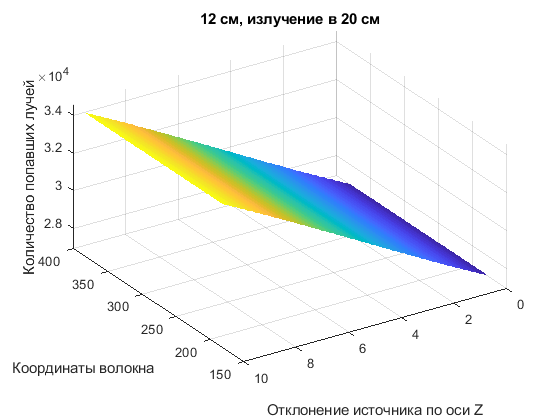

ff(:,:) = LossPosition(2,:,:);
figure
[X, Y] = meshgrid(firstScreenCoord + (1:1:maxEra),10:-0.1:0);
mesh(X,Y,ff)

title('12 см, излучение в 20 см')
zlabel('Количество попавших лучей')
ylabel('Отклонение источника по оси Z')
xlabel('Координаты волокна')

view([-123 43])

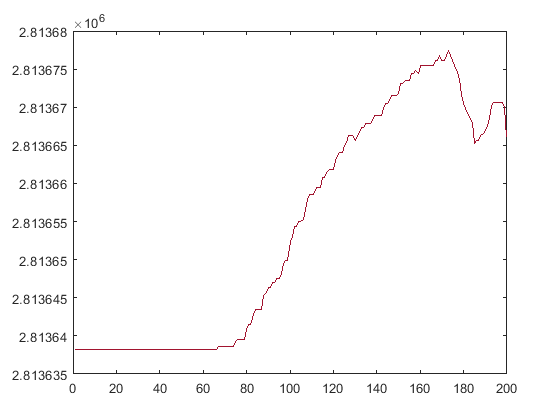


figure
grid on;
for i = 1:1:size(LossPosition,1)
ff(:,:) = LossPosition(3,:,:);
plot(sum(ff,1))
hold on
end

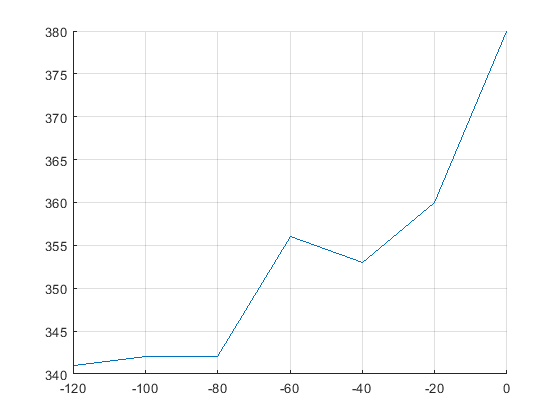

figure
grid on;
for i = 1:1:size(LossPosition,1)
ff(:,:) = LossPosition(i,:,:);
[~, J(i)] = max(sum(ff,1));
hold on
end
plot(LIGTHCoord,firstScreenCoord +J)